# Prerequisites for code generation

Generating code for a deep learning model has certain prerequisites that must be met. These include installation of certain products, support packages and compilers. The following steps lists these prerequisites to generate a static library using MKL-DNN and a ROS node using CUDA. More information on prerequisites for generating [MATLAB code](https://www.mathworks.com/help/coder/ug/prerequisites-for-deep-learning-with-matlab-coder.html) and [GPU code](https://www.mathworks.com/help/gpucoder/gs/install-prerequisites.html) can be found in the linked documentation

### Required products and support packages:

- MATLAB Coder™

- Embedded Coder® (For ROS node generation)

- GPU Coder™ (For ROS node generation)

- ROS Toolbox (For ROS node generation)

- Deep Learning Toolbox™

- MATLAB Coder Support Package for NVIDIA®  Jetson™ and NVIDIA DRIVE®  Platforms (For ROS node generation)

- GPU Coder Interface for Deep Learning support package

- Parallel Computing Toolbox™

### Required Compiler

The [recommended compiler](https://www.mathworks.com/support/requirements/supported-compilers.html) for this application is Microsoft Visual C++ (2017, 2019, 2022). You can check the current compiler by running the following line of code. The output also lists available compiler options and how to switch to a different compiler.

mex -setup

MEX configured to use 'Microsoft Visual C++ 2019 (C)' for C language compilation.

To choose a different C compiler, select one from the following:
MinGW64 Compiler (C)  mex -setup:'C:\Program Files\MATLAB\R2024b\bin\win64\mexopts\mingw64.xml' C
Microsoft Visual C++ 2019 (C)  mex -setup:C:\Users\abshanka\AppData\Roaming\MathWorks\MATLAB\R2024b\mex_C_win64.xml C

To choose a different language, select one from the following:
 mex -setup C++ 
 mex -setup FORTRAN


mex -setup C++

MEX configured to use 'Microsoft Visual C++ 2019' for C++ language compilation.

To choose a different C++ compiler, select one from the following:
MinGW64 Compiler (C++)  mex -setup:'C:\Program Files\MATLAB\R2024b\bin\win64\mexopts\mingw64_g++.xml' C++
MinGW64 Compiler with Windows 10 SDK or later (C++)  mex -setup:'C:\Program Files\MATLAB\R2024b\bin\win64\mexopts\mingw64_g++_sdk10+.xml' C++
Microsoft Visual C++ 2019  mex -setup:C:\Users\abshanka\AppData\Roaming\MathWorks\MATLAB\R2024b\mex_C++_win64.xml C++


### External products/libraries

In addition to the listed MathWorks products and support packages, some external libraries are required to compile the generated code. These are listed in the documentation pages linked above and they will be listed below for convenience

- Intel MKL-DNN (This library is used if there's no supported GPU to make use of the CUDA capabilities)

- CUDA (For ROS node generation)

- NVIDIA cuDNN (For ROS node generation)

- TensorRT (the live script does not require this product but if you wish to use TensorRT instead of CUDA, please install this) (For ROS node generation)

### Environment Variables

MATLAB uses the following environment variables to look for specific libraries, Please make sure these are set. The variables with '*' are optional and not used in this workflow. Further, these are for windows system running MKL-DNN and generating CUDA code using cuDNN. The environment variables for Linux or MacOS and other deep learning libraries can be found in the linked documentation page.

# Deploying the Trained Network

Once the network has been trained, the next step is to deploy the network to integrate into your workflow. You can deploy your model in a few ways such as an executable, static/dynamic library, etc. The method to choose depends on the application and the target hardware. If you have your LiDAR data coming in as ROS messages, it might be easier to deploy your model as an executable ROS node. If you just want a library that you can call from your current codebase, it makes more sense to generate a static or a dynamic library. Moreover, the hardware choices also play a factor in this process. For example, the Jetson boards have CUDA cores that can be used to speed up inference, in that case, you can utilize those to speed the model performance. 

In this demo, we'll see how to generate a static library and an executable ROS2 node from the trained network. The typical code generation workflow for a machine or deep learning model looks like this

## Option 1: Generating a Static Library

### Inference Function

To get started, let's create a function [`pillarPredict`](matlab:open('./pillarPredict.m')) that loads the trained network, makes a prediction, and returns the detection results.

The function loads the trained detector and takes a 3D array of points as input. This is to ensure the coder knows the size of the input, after which it is converted to a pointCloud object before passing to the network. 

### Entry Point Script

Before configuring the coder, let's create an entry point script. This helps in defining the input and output variable types and shapes.

% Load a test data point and convert it from point cloud to 3D array
pcloud = pcread("..\testData\frame_0001.pcd");
pcloud_3d = pcloud.Location;
intensities = pcloud.Intensity;
[bboxes, scores, labels] = pillarPredict(pcloud_3d, intensities);

### Coder Configuration

We'll next open MATLAB Coder and set it up to generate a static library. The code generation function will be the `pillarPredict` function and the entry point script is the entry point function shown above.

coder

Ensure that 'Enable code generation for deep learning' is checked and the right library is used. This can be set under Settings -> Deep Learning as shown below.

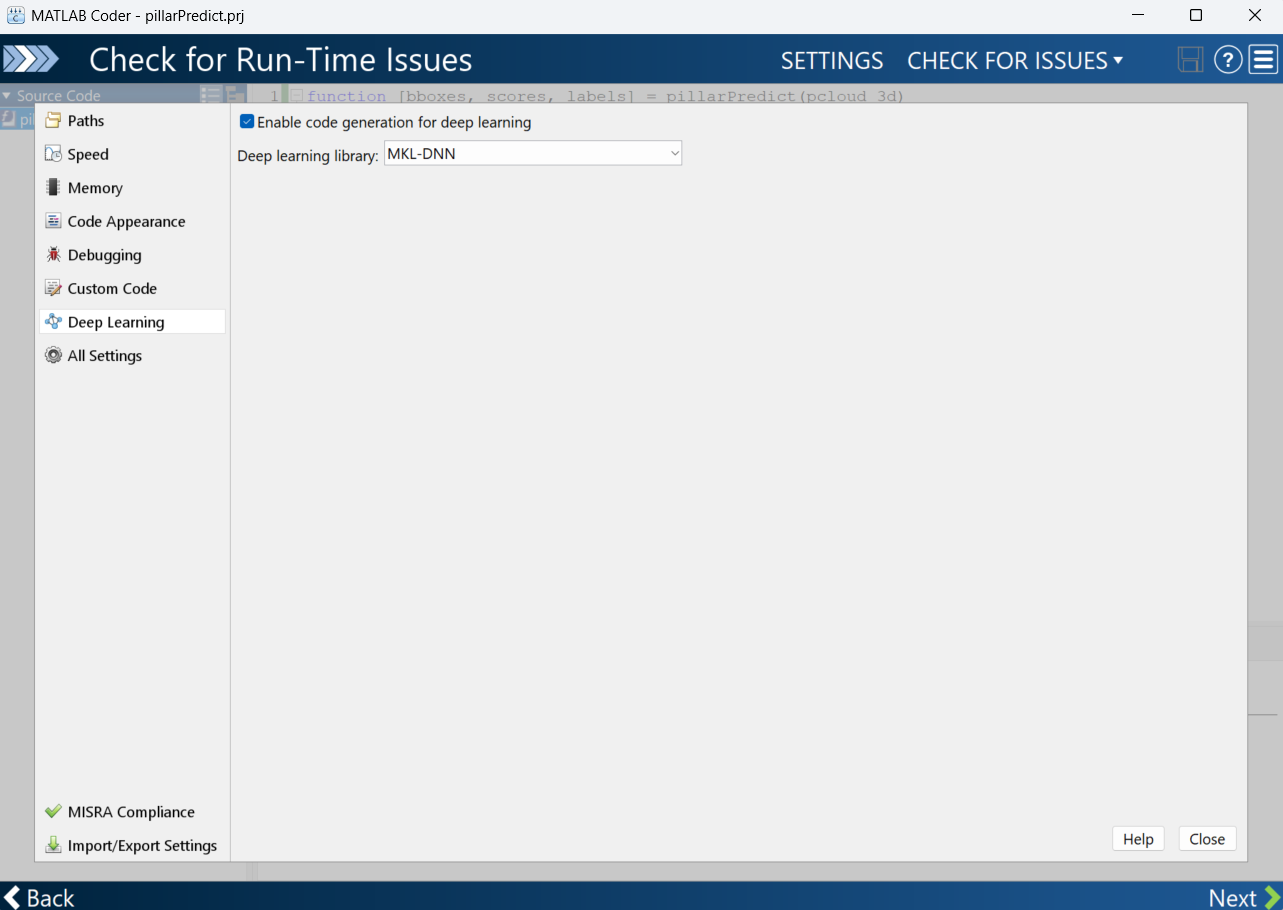

The next step is to generate code. Here, choose a static library which can be linked with an external project. You can also choose the other options if you feel that would be better suited for your application. Then click 'Generate' to begin code generation, which can then be used with your project!

## ROS Node Generation

In this demo, we'll see how to generate a ROS2 node that subscribes to a point cloud message and publishes the inference of the trained network.

### Coder configuration

To get started, let's setup MATLAB Coder to generate a ROS2 node and to use the appropriate deep learning library. For this example, we'll set it up programmatically and we'll generate a node that can run on a Jetson Orin Nano using the CUDNN library, which uses CUDA cores to speed up inference.

% Setup the coder to generate a ROS2 node on a remote device
cfg = coder.config("exe");
cfg.Hardware = coder.hardware("Robot Operating System 2 (ROS 2)");
cfg.Hardware.DeployTo = "Remote Device";
cfg.Hardware.BuildAction = "Build and run";
% The Jetson board has an ARM 64 bit processor so we choose that as the
% device type
cfg.HardwareImplementation.ProdHWDeviceType = "ARM Compatible->ARM 64-bit (LLP64)";
cfg.HardwareImplementation.ProdLongLongMode = true;
% The next three lines sets up the GPU coder and sets up to use CUDNN
cfg.GpuConfig = coder.GpuCodeConfig;
cfg.GpuConfig.Enabled = true;
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
% The last 4 lines provides information of the remote device so the coder
% can transfer the generated code and build it.
cfg.Hardware.RemoteDeviceAddress = '172.21.89.193';
cfg.Hardware.ROS2Workspace = '/home/ubuntu/ros2_ws';
cfg.Hardware.RemoteDeviceUsername = 'ubuntu';
cfg.Hardware.RemoteDevicePassword = 'ubuntu';

### ROS 2 node creation

With the coder setup, the next step is to create a MATLAB ROS2 node that can then be used to generate a CUDA ROS node. For this example, we'll write a function [`lidarInfer`](matlab:open('./lidarInfer.m')) that creates a simple node that subscribes to the point cloud topic and publishes the bounding box location and object labels.

Here, we are subscribing to the topic "static_cloud" which is being published by another node that reads the point cloud file. We set the rate to 30Hz but this would depend on the hardware you use and the inference speed that can be achieved along with the rate at which the LiDAR is publishing. 

The main loop shown above reads the point cloud message and then passes it to the [`pillarPredict`](matlab:open('./pillarPredict.m')) function which is shown below. The inference results from the trained network are then passed into the bounding box and label variables before being published. 

The pillarPredict function loads the trained networks and returns the inference results. Since the network accepts a pointCloud as an input, we convert the raw 3 dimensional matrix to a point cloud and pass it to the network. For the purpose of code generation, we'll also save these functions as a separate file, making it easier to pass it to the code gen function.

### Code Generation

With the code and the coder setup, we can now generate code and have it run on the Jetson. Code generation takes only a single line to pass in the function and the coder setup.

codegen lidarInfer -config cfg

The generated code is then transferred to the remote device and built before being executed. Now the node runs on the Jetson independent of MATLAB and can be stopped or started again through the device.